load('IRIS_DMC_with_FMS.mat')
minMag = 6;
MSCat = aftershock_productivity_kernel(...
    CAT.time, ...
    CAT.lat, ...
    CAT.lon, ...
    CAT.depth, ...
    CAT.M, ...
    CAT.fms, ...
    'MinMainshockMag',minMag, ...
    'DepthRange',[0,55], ...
    'ReturnCatalog', 'yes', ...
    'SaveCatalog', 'no', ...
    'PlotYN','no');


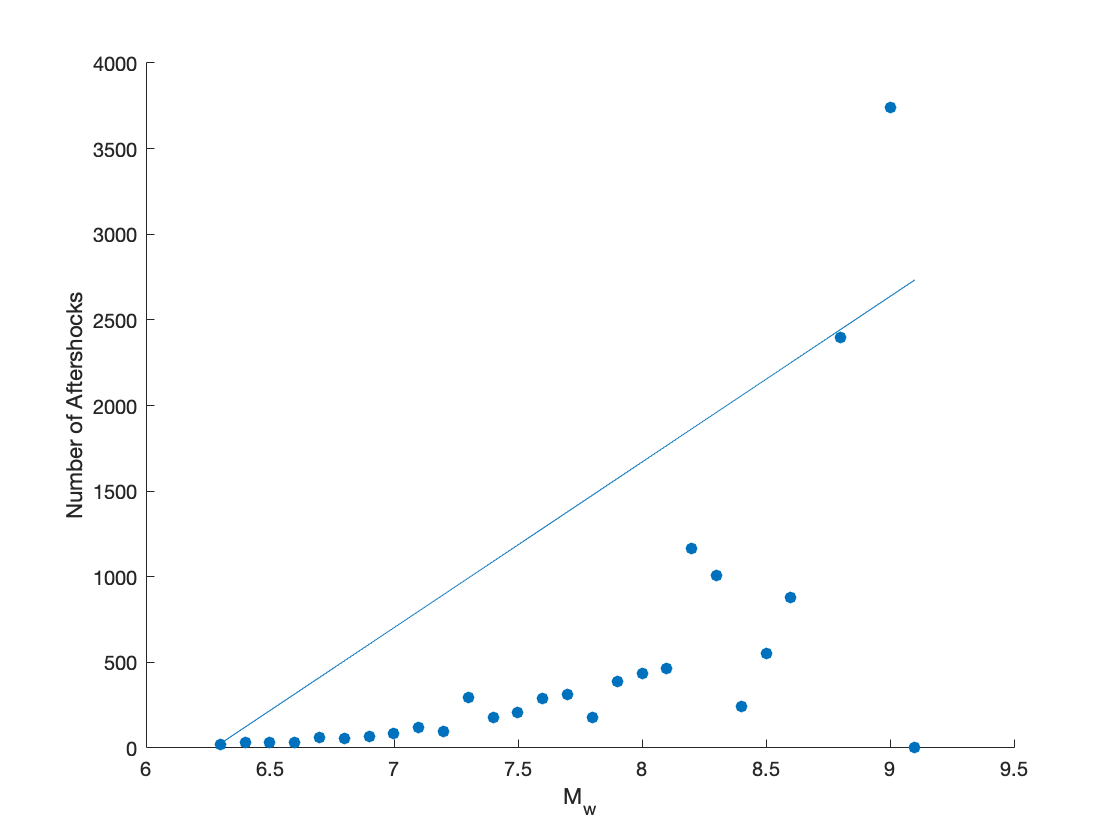

figure; hold on;
M   = MSCat.MSmag;
t   = MSCat.MSt;
res = MSCat.MSres;
prod= MSCat.MSprod;
fms = MSCat.MSfms;

figure